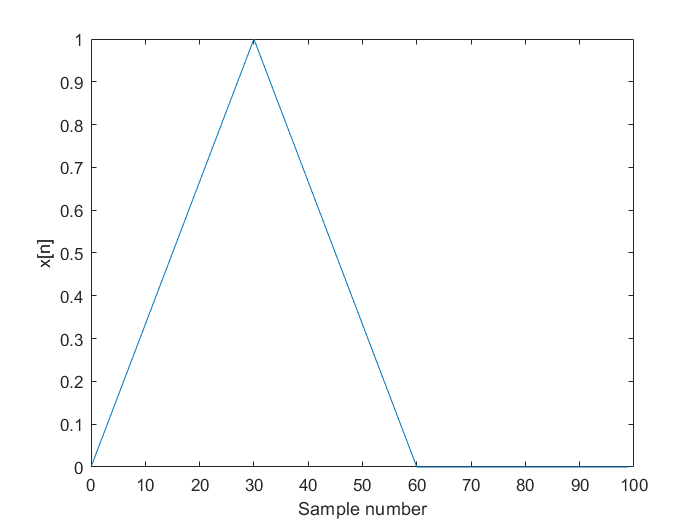

clear all;      
close all;
clc;

x = 0:99;
y = (30 - abs(x-30)) / 30;
y(61:100) = 0;
plot(x,y);
xlabel('Sample number');
ylabel('x[n]')

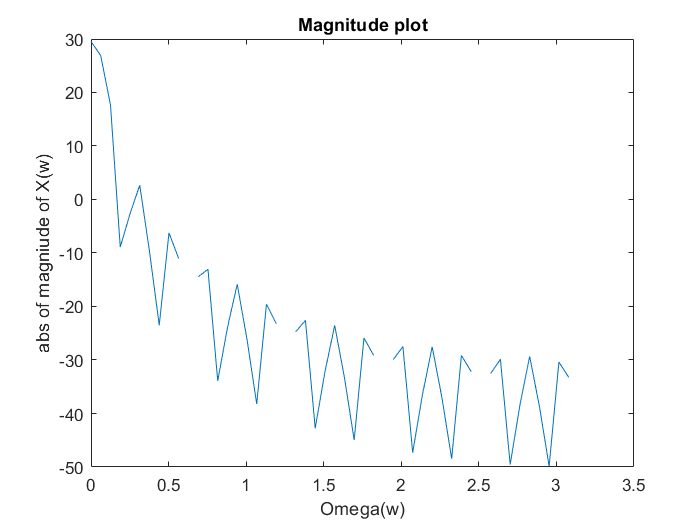


L = length(y);
Xw = fft(y);
Xw_half_frequency = Xw(1:L/2);
Omega = 0:pi/50:49/50*pi;
% Omega = 0:pi/100:99/100*pi;
plot(Omega, mag2db(abs(Xw_half_frequency)));
% plot(Omega, mag2db(abs(Xw)))
xlabel('Omega(w)');
ylabel('abs of magniude of X(w)');
title('Magnitude plot');

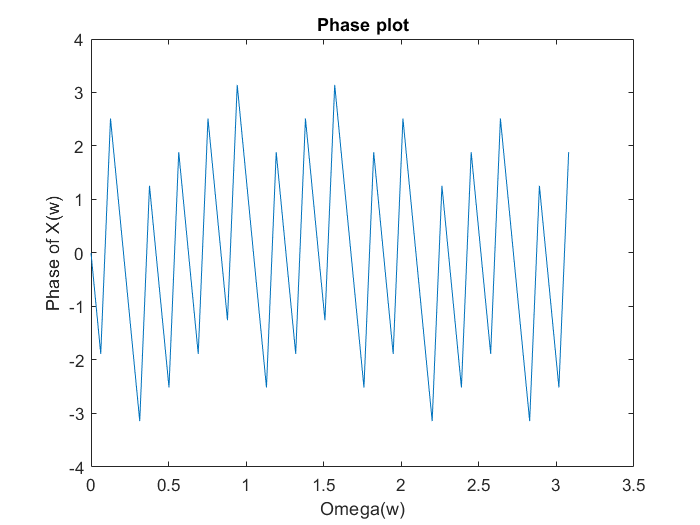


phase = angle(Xw);
phase_half_frequency = phase(1:L/2);
plot(Omega, phase_half_frequency);
xlabel('Omega(w)');
ylabel('Phase of X(w)');
title('Phase plot');    